% Coeficientes do numerador e denominador 
b = 0.094 * [1, 4, 6, 4, 1];
a = [1, 0, 0.486, 0, 0.0177];

roots(b)

ans =   -1.0001 + 0.0001i
  -1.0001 - 0.0001i
  -0.9999 + 0.0001i
  -0.9999 - 0.0001i


roots(a)

ans =    0.0000 + 0.6681i
   0.0000 - 0.6681i
   0.0000 + 0.1991i
   0.0000 - 0.1991i


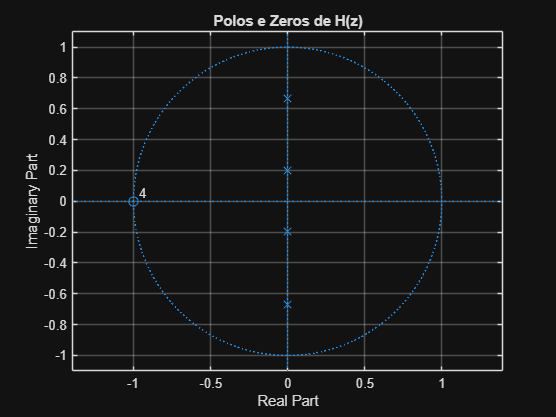


% Diagrama de polos e zeros
zplane(b, a);
title('Polos e Zeros de H(z)');
grid on;

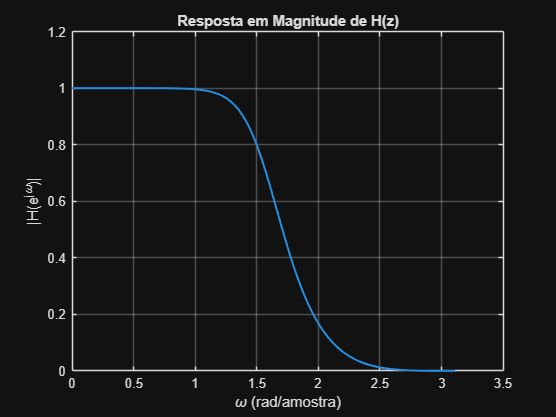


% Resposta em frequencia (magnitude)
[H, w] = freqz(b, a, 100);

plot(w, abs(H), 'LineWidth', 1.5);
xlabel('\omega (rad/amostra)');
ylabel('|H(e^{j\omega})|');
title('Resposta em Magnitude de H(z)');
grid on;